## Transonic Aerodynamics - HW1

Shalom Carmona

Nicolas Tran

Steady 1D Euler equations

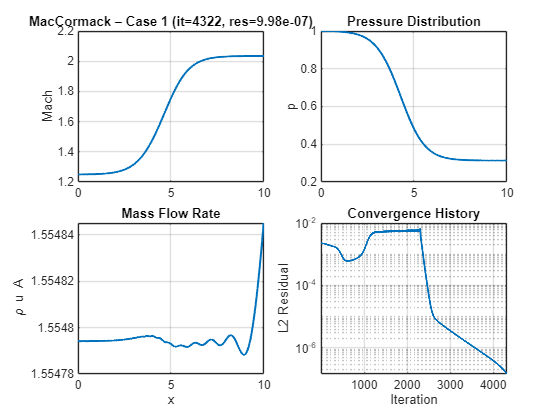

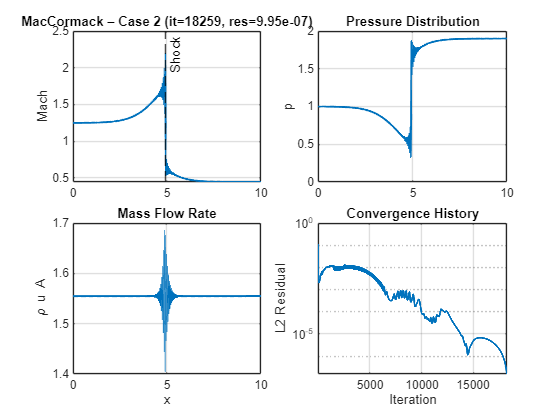

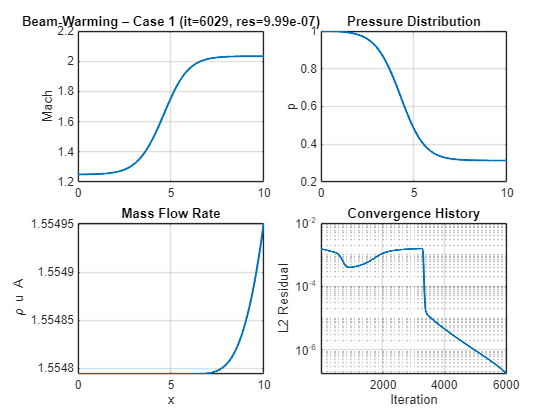

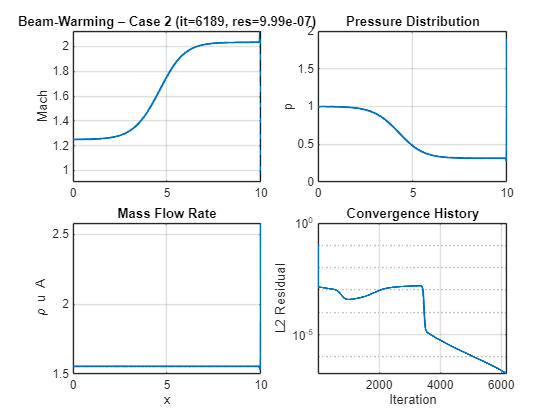

clear; clc; close all;

%params
gamma = 1.4;
cfl   = 0.5; % pseudo-time CFL
N     = 401; % grid points
L     = 10;
Min   = 1.25; % inlet mach
rho_in = 1; T_in = 1; p_in = rho_in*T_in;
p_back_factor = 1.9; % for case 2
maxIter = 2e4; tol = 1e-6;

% geom
x  = linspace(0,L,N); dx = x(2)-x(1);
A  = 1.398 + 0.347*tanh(0.8*x - 4);
dA = 0.347*0.8*(1 - tanh(0.8*x - 4).^2);

% inlet prim state
a_in = sqrt(gamma*p_in/rho_in);
u_in = Min*a_in;
e_in = p_in/(gamma-1) + 0.5*rho_in*u_in^2;

% two methods: MacCormack and Beam-Warming
methods = {'MacCormack', 'Beam-Warming'};

for method_idx = 1:2
    method_name = methods{method_idx};
    
    % two cases
    for case_id = [1 2]
        if method_idx == 1
            [Q, it, res, resHist] = macCormack_nozzle(gamma, cfl, x, A, dA, ...
                rho_in, u_in, e_in, p_in, p_back_factor, maxIter, tol, case_id);
        else
            [Q, it, res, resHist] = beamWarming_nozzle(gamma, cfl, x, A, dA, ...
                rho_in, u_in, e_in, p_in, p_back_factor, maxIter, tol, case_id);
        end

        % post-process
        rho = Q(1,:)./A; u = Q(2,:)./(rho.*A); e = Q(3,:)./A;
        p = (gamma-1)*(e - 0.5*rho.*u.^2);
        M = u./sqrt(gamma*p./rho);
        mdot = rho.*u.*A;

        % shock estimate
        xshock = NaN;
        if case_id==2
            k = find(M(1:end-1)>1 & M(2:end)<1,1);
            if ~isempty(k)
                xshock = x(k) + (1-M(k))*(x(k+1)-x(k))/(M(k+1)-M(k));
            end
        end

        %plots
        figure('Name',sprintf('%s - Case %d',method_name,case_id));
        tiledlayout(2,2,"TileSpacing","compact");
        
        % Mach number
        nexttile; plot(x,M,'LineWidth',1.5); grid on; ylabel('Mach');
        title(sprintf('%s – Case %d (it=%d, res=%.2e)',method_name,case_id,it,res));
        if case_id==2 && ~isnan(xshock), xline(xshock,'k--','Shock'); end
        
        % Pressure
        nexttile; plot(x,p,'LineWidth',1.5); grid on; ylabel('p');
        title('Pressure Distribution');
        
        % Mass flow
        nexttile; plot(x,mdot,'LineWidth',1.5); grid on; ylabel('\rho u A'); xlabel('x');
        title('Mass Flow Rate');
        
        % Convergence history
        nexttile; 
        semilogy(1:length(resHist), resHist, 'LineWidth',1.5); 
        grid on; xlabel('Iteration'); ylabel('L2 Residual');
        title('Convergence History');
        xlim([1 length(resHist)]);
    end
end


%% MacCormack Solver
function [Q, it, res, resHist] = macCormack_nozzle(gamma, cfl, x, A, dAdx, ...
    rho_in, u_in, e_in, p_in, p_back_factor, maxIter, tol, case_id)

N = numel(x); dx = x(2)-x(1);
Q = zeros(3,N);
Q(1,:) = rho_in*A; Q(2,:) = rho_in*u_in*A; Q(3,:) = e_in*A;

useAV = (case_id==2); k2 = 0.06; epsTiny = 1e-12;

res = inf; it = 0;
resHist = []; % store convergence history

while it<maxIter && res>tol
    it = it + 1;

    % primitives
    rho = Q(1,:)./A; 
    rho = max(rho, 1e-10); % prevent negative density
    u = Q(2,:)./(rho.*A); 
    e = Q(3,:)./A;
    p = (gamma-1)*(e - 0.5*rho.*u.^2);
    p = max(p, 1e-10); % prevent negative pressure
    a = sqrt(gamma*p./rho);
    dt = min( cfl*dx ./ (abs(u)+a) );

    % flux & source
    F = [rho.*u.*A; (rho.*u.^2+p).*A; u.*(e+p).*A];
    S = [zeros(1,N); p.*dAdx; zeros(1,N)];

    % av jameson 2nd-diff
    D = zeros(3,N);
    if useAV
        num = abs([p(2)-2*p(1)+p(2), p(3:end)-2*p(2:end-1)+p(1:end-2), p(end-1)-2*p(end)+p(end-1)]);
        den = p(3:end)+2*p(2:end-1)+p(1:end-2)+epsTiny;
        eps2 = zeros(1,N); eps2(2:end-1) = k2*(num(2:end-1)./den);
        for m=1:3
            D(m,2:end-1) = eps2(2:end-1).*(Q(m,3:end)-2*Q(m,2:end-1)+Q(m,1:end-2));
        end
    end

    % predictor
    Qp = Q;
    for i=1:N-1
        AVp = (D(:,i+1)-D(:,i))/dx;
        Qp(:,i) = Q(:,i) - dt/dx*(F(:,i+1)-F(:,i)) + dt*S(:,i) - dt*AVp;
    end

    % predicted flux/source
    rhop = Qp(1,:)./A; up = Qp(2,:)./(rhop.*A); ep = Qp(3,:)./A;
    pp = (gamma-1)*(ep - 0.5*rhop.*up.^2);
    Fp = [rhop.*up.*A; (rhop.*up.^2+pp).*A; up.*(ep+pp).*A];
    Sp = [zeros(1,N); pp.*dAdx; zeros(1,N)];

    Dp = zeros(3,N);
    if useAV
        num = abs([pp(2)-2*pp(1)+pp(2), pp(3:end)-2*pp(2:end-1)+pp(1:end-2), pp(end-1)-2*pp(end)+pp(end-1)]);
        den = pp(3:end)+2*pp(2:end-1)+pp(1:end-2)+epsTiny;
        eps2 = zeros(1,N); eps2(2:end-1) = k2*(num(2:end-1)./den);
        for m=1:3
            Dp(m,2:end-1) = eps2(2:end-1).*(Qp(m,3:end)-2*Qp(m,2:end-1)+Qp(m,1:end-2));
        end
    end

    % corrector
    Qn = Q;
    for i=2:N
        AVc = (Dp(:,i)-Dp(:,i-1))/dx;
        Qn(:,i) = 0.5*( Q(:,i)+Qp(:,i) - dt/dx*(Fp(:,i)-Fp(:,i-1)) + dt*Sp(:,i) - dt*AVc );
    end

    % bcs: supersonic inlet - full state
    Qn(:,1) = [rho_in*A(1); rho_in*u_in*A(1); e_in*A(1)];

    if case_id==1
        % supersonic outlet: extrapolate
        Qn(:,end) = Qn(:,end-1);
    else
        % subsonic outlet: p = 1.9 p_in
        p_back = p_back_factor * p_in;
        rhoN = Qn(1,end)/A(end);
        uN   = (Qn(2,end)/A(end))/rhoN;
        eN   = p_back/(gamma-1) + 0.5*rhoN*uN^2;
        Qn(:,end) = [rhoN*A(end); rhoN*uN*A(end); eN*A(end)];
    end

    res = max(abs(Qn(:)-Q(:)));
    
    % store L2 norm of residual before updating Q
    resHist(it) = sqrt(sum((Qn(:)-Q(:)).^2) / numel(Q));
    
    Q   = Qn;
end
end

%% Beam-Warming Implicit Solver
function [Q, it, res, resHist] = beamWarming_nozzle(gamma, cfl, x, A, dAdx, ...
    rho_in, u_in, e_in, p_in, p_back_factor, maxIter, tol, case_id)

N = numel(x); dx = x(2)-x(1);
Q = zeros(3,N);
Q(1,:) = rho_in*A; Q(2,:) = rho_in*u_in*A; Q(3,:) = e_in*A;

% artificial dissipation constants
eps_e = 0.02;  % explicit dissipation (reduced for stability)
eps_i = 0.10;  % implicit dissipation (should be > 2*eps_e)
epsTiny = 1e-12;

res = inf; it = 0;
resHist = []; % store convergence history

while it<maxIter && res>tol
    it = it + 1;

    % primitives
    rho = Q(1,:)./A; 
    rho = max(rho, 1e-10); % prevent negative density
    u = Q(2,:)./(rho.*A); 
    e = Q(3,:)./A;
    p = (gamma-1)*(e - 0.5*rho.*u.^2);
    p = max(p, 1e-10); % prevent negative pressure
    a = sqrt(gamma*p./rho);
    dt = min( cfl*dx ./ (abs(u)+a) );

    % flux & source
    F = zeros(3,N);
    S = [zeros(1,N); p.*dAdx; zeros(1,N)];
    for i = 1:N
        F(:,i) = [rho(i)*u(i)*A(i); 
                  (rho(i)*u(i)^2+p(i))*A(i); 
                  u(i)*(e(i)+p(i))*A(i)];
    end

    % flux Jacobian matrices
    Ajac = zeros(3,3,N);
    for i = 1:N
        H = (e(i) + p(i))/rho(i);
        u2 = u(i)^2;
        Ajac(:,:,i) = [0, 1, 0;
                       (gamma-3)/2*u2, (3-gamma)*u(i), gamma-1;
                       u(i)*((gamma-1)*u2/2 - H), H - (gamma-1)*u2, gamma*u(i)];
    end

    % RHS: -∂E/∂x + S - explicit dissipation
    RHS = zeros(3,N);
    
    for i = 2:N-1
        % backward difference for flux derivative
        dEdx = (F(:,i) - F(:,i-1))/dx;
        
        % explicit 4th-order artificial dissipation: -eps_e*(∇Δ)²Q
        if i >= 3 && i <= N-2
            % (∇Δ)²Q = Q_{i+2} - 4Q_{i+1} + 6Q_i - 4Q_{i-1} + Q_{i-2}
            visc_term = eps_e * (Q(:,i+2) - 4*Q(:,i+1) + 6*Q(:,i) - 4*Q(:,i-1) + Q(:,i-2));
            RHS(:,i) = -dEdx + S(:,i) - visc_term/dx;
        else
            RHS(:,i) = -dEdx + S(:,i);
        end
    end

    % Build implicit system: [I + θΔt(∂A/∂x) - εᵢΔt(∇Δ)²]ΔQ = ΔtRHS
    % Simplified: use diagonal approximation to avoid singular matrices
    theta = 1.0;
    
    Lower = zeros(3,3,N);
    Diag = zeros(3,3,N);
    Upper = zeros(3,3,N);
    b = zeros(3,N);
    
    for i = 2:N-1
        % Use eigenvalue-based diagonal approximation for stability
        lambda = abs(u(i)) + a(i);  % maximum wave speed
        
        % Implicit dissipation: tridiagonal second-order operator
        visc_coef = eps_i * dt / (dx*dx);
        
        % Diagonal-dominant tridiagonal system
        Lower(:,:,i) = -visc_coef * eye(3);
        Diag(:,:,i) = eye(3) * (1 + 2*visc_coef + theta*dt*lambda/dx);
        Upper(:,:,i) = -visc_coef * eye(3);
        
        b(:,i) = dt * RHS(:,i);
    end
    
    % boundary conditions
    Diag(:,:,1) = eye(3);
    Upper(:,:,1) = zeros(3);
    b(:,1) = [0; 0; 0];
    
    Diag(:,:,N) = eye(3);
    Lower(:,:,N) = zeros(3);
    b(:,N) = [0; 0; 0];
    
    % solve block tridiagonal system
    dQ = blockThomas(Lower, Diag, Upper, b, N);

    % update solution
    Qn = Q + dQ;

    % apply boundary conditions
    Qn(:,1) = [rho_in*A(1); rho_in*u_in*A(1); e_in*A(1)];

    if case_id==1
        Qn(:,end) = Qn(:,end-1);
    else
        p_back = p_back_factor * p_in;
        rhoN = Qn(1,end)/A(end);
        uN   = (Qn(2,end)/A(end))/rhoN;
        eN   = p_back/(gamma-1) + 0.5*rhoN*uN^2;
        Qn(:,end) = [rhoN*A(end); rhoN*uN*A(end); eN*A(end)];
    end

    res = max(abs(Qn(:)-Q(:)));
    
    % store L2 norm of residual before updating Q
    resHist(it) = sqrt(sum((Qn(:)-Q(:)).^2) / numel(Q));
    
    Q   = Qn;
end
end

%% Block Thomas algorithm for block tridiagonal system
function x = blockThomas(L, D, U, b, N)
    % Solves block tridiagonal system with 3x3 blocks
    % L: lower diagonal blocks (3x3xN)
    % D: main diagonal blocks (3x3xN)
    % U: upper diagonal blocks (3x3xN)
    % b: RHS vectors (3xN)
    
    D_star = zeros(3,3,N);
    b_star = zeros(3,N);
    x = zeros(3,N);
    
    % Forward elimination with pivoting/conditioning
    D_star(:,:,1) = D(:,:,1);
    
    % Add small regularization to diagonal for numerical stability
    reg = 1e-10;
    D_star(:,:,1) = D_star(:,:,1) + reg*eye(3);
    
    b_star(:,1) = D_star(:,:,1) \ b(:,1);
    
    for i = 2:N
        % Compute: D* = D - L*(D*_{i-1})^{-1}*U
        D_inv_prev = inv(D_star(:,:,i-1) + reg*eye(3));
        D_star(:,:,i) = D(:,:,i) - L(:,:,i) * D_inv_prev * U(:,:,i-1);
        
        % Add regularization
        D_star(:,:,i) = D_star(:,:,i) + reg*eye(3);
        
        % Compute: b* = (D*)^{-1} * (b - L*b*_{i-1})
        b_star(:,i) = D_star(:,:,i) \ (b(:,i) - L(:,:,i) * b_star(:,i-1));
    end
    
    % Back substitution
    x(:,N) = b_star(:,N);
    for i = N-1:-1:1
        D_inv = inv(D_star(:,:,i) + reg*eye(3));
        x(:,i) = b_star(:,i) - D_inv * U(:,:,i) * x(:,i+1);
    end
end

